## AAE334 HW12 P2

clear all; close all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2020-Spring\AAE334\matlab\outputs\HW12';
set(groot, 'defaulttextinterpreter',"latex");
set(groot, 'defaultAxesTickLabelInterpreter',"latex");
set(groot, 'defaultLegendInterpreter',"latex");

% Global constants 
gamma = 1.4;

### a)

% Import data 
xdata = read_txt_file("inputs\hw12\airfoil_x.txt");
ydata = read_txt_file("inputs\hw12\airfoil_y.txt");
Cpdata = read_txt_file("inputs\hw12\airfoil_cp.txt");

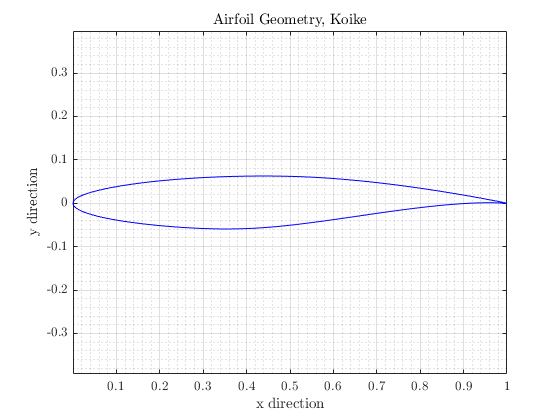

% Plot the airfoil geometry 
fig = figure("Renderer","painters");
    plot(xdata,ydata,'-b');
    title({'Airfoil Geometry, Koike'});
    xlabel('x direction');
    ylabel('y direction');
    axis equal; grid on; grid minor; box on;
saveas(fig,fullfile(fdir,"airfoil.png"));

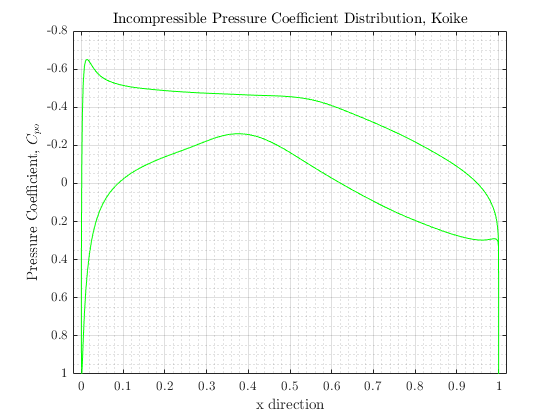

% Plot the incompressible pressure coefficient distribution
fig = figure("Renderer","painters");
    plot(xdata,Cpdata,'-g');
    title("Incompressible Pressure Coefficient Distribution, Koike");
    xlabel('x direction')
    ylabel("Pressure Coefficient, $C_{po}$")
    grid on; grid minor; box on; xlim([-0.02,1.02]);
    set(gca,'ydir','reverse');
saveas(fig,fullfile(fdir,"pressure_coeff.png"));

% Find the minimum Cpo
Cpo_min = min(Cpdata);

### b)

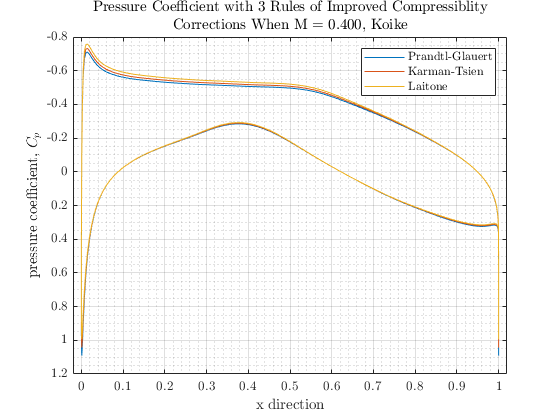

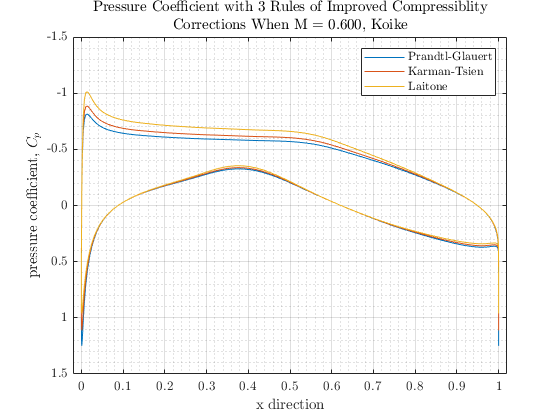

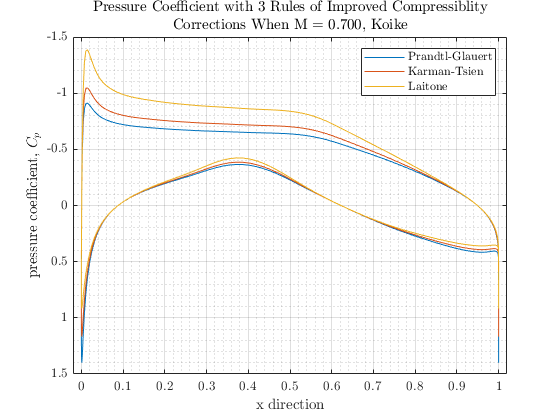

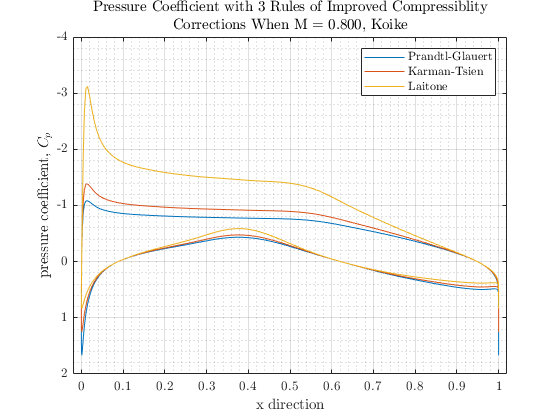

% Computing the correct pressure coefficients based on subsonic condtions using 
% Prandtl-Glauert, Karman-Tsien, and Latione formulas

% Mach numbers to investigate
M_b = [0.40 0.60 0.70 0.80];

% Preallocating an array to store all results 
Cp_PG = zeros([numel(Cpdata),numel(M_b)]);
Cp_KT = zeros([numel(Cpdata),numel(M_b)]);
Cp_La = zeros([numel(Cpdata),numel(M_b)]);

% Loop to conduct calculations
for i = 1:length(M_b)
    M_i = M_b(i);
    Cp_PG(:,i) = Prandtl_Glauert(Cpdata,M_i);
    Cp_KT(:,i) = Karman_Tsien(Cpdata,M_i);
    Cp_La(:,i) = Laitone(Cpdata,M_i,gamma);
    
    % Plotting 
    fig = figure(i);
        plot(xdata,Cp_PG(:,i))
        txt1 = "Pressure Coefficient with 3 Rules of Improved Compressiblity";
        txt2 = sprintf("Corrections When M = %.3f, Koike",M_i);
        title({txt1, txt2})
        xlabel('x direction')
        ylabel('pressure coefficient, $C_{p}$')
        hold on
        plot(xdata,Cp_KT(:,i))
        plot(xdata,Cp_La(:,i))
        hold off; grid on; grid minor; box on; xlim([-0.02,1.02]);
        legend('Prandtl-Glauert','Karman-Tsien',"Laitone","Location",'northeast')
        set(gca,'ydir','reverse');
    file_txt = sprintf("3rulesPlot_M%.3f.png",M_i);
    saveas(fig,fullfile(fdir,file_txt));
end

% Minimum pressure coefficients
min_Cp_PG = min(Cp_PG);
min_Cp_KT = min(Cp_KT);
min_Cp_La = min(Cp_La);
arr = [min_Cp_PG.' min_Cp_KT.' min_Cp_La.'];
T = array2table(arr,"VariableNames",{'Prandtl-Glauert','Karman-Tsien','Laitone'});
writetable(T,fullfile(fdir,'3rules_min_Cp.xlsx'),"WriteMode","overwritesheet");

### c)

Cpcr = critical_Cp(M_b,gamma);
arr_p = abs(T{:,:} - Cpcr.');
T_p = array2table(arr_p,"VariableNames",{'Prandtl-Glauert','Karman-Tsien','Laitone'});
writetable(T_p,fullfile(fdir,'3rules_diff_Cp.xlsx'),"WriteMode","overwritesheet");

### d)

% Compute the Critical Mach Number using Optimization - PatternSearch

% Prandtl-Glauert
M0 = 0.2;
lb = 0.01; ub = 0.95;
A = []; b = [];
Aeq = []; beq = [];
objfunc = @(M) opt_Prandtl_Glauert_Mcr(M,Cpo_min,gamma);
[Mcr_PG, fval_PG] = patternsearch(objfunc,M0,A,b,Aeq,beq,lb,ub);

Optimization terminated: mesh size less than options.MeshTolerance.



% Karman-Tsien 
objfunc = @(M) opt_Karman_Tsien_Mcr(M,Cpo_min,gamma);
[Mcr_KT, fval_KT] = patternsearch(objfunc,M0,A,b,Aeq,beq,lb,ub);

Optimization terminated: mesh size less than options.MeshTolerance.



% Laitone
objfunc = @(M) opt_Laitone_Mcr(M,Cpo_min,gamma);
[Mcr_La, fval_La] = patternsearch(objfunc,M0,A,b,Aeq,beq,lb,ub);

Optimization terminated: mesh size less than options.MeshTolerance.


### d)

Mn = 0.85;
sigma = acosd(Mcr_KT/Mn);

### FUNCTIONS

function data = read_txt_file(file_str)
    % This function reads a txt.file and imports the data as an array
    afile = fopen(file_str,'r');
    formatSpec = '%f';
    data = fscanf(afile,formatSpec);
    fclose(afile);
end

function Cp = Prandtl_Glauert(Cpo,M)
    % Function that calculates the subsonic linear theory using
    % Prandtl-Glauert formula 
    Cp = Cpo./sqrt(1 - M.^2);
end

function Cp = Karman_Tsien(Cpo,M)
    % Function that calculates the subsonic linear theory using
    % Karman-Tsien formula
    a1 = sqrt(1 - M.^2);
    a2 = M^2./(1 + sqrt(1 - M.^2));
    Cp = Cpo./(a1 + a2*Cpo/2);
end

function Cp = Laitone(Cpo,M,gamma)
    % Function that calculates the subsonic linear theory using Latione
    % formula
    a1 = sqrt(1 - M.^2);
    a2 = (1 + (gamma - 1)/2.*M.^2);
    a3 = M^2.*a2/2./sqrt(1 - M.^2);
    Cp = Cpo./(a1 + a3.*Cpo);
end

function Cpcr = critical_Cp(M,gamma)
    % This function computes the critical pressure coefficient for a given
    % Mach number
    a1 = 2/gamma./M.^2;
    a2 = 1 + (gamma - 1)/2.*M.^2;
    a3 = (gamma + 1)/2;
    a4 = gamma/(gamma - 1);
    Cpcr = a1.*((a2./a3).^a4 - 1);
end

function G_M = opt_Prandtl_Glauert_Mcr(M,Cpo_min,gamma)
    % Expression of critical pressure coefficient function
    A1 = 2/gamma/M^2;
    A2 = 1 + (gamma - 1)/2*M^2;
    A3 = (gamma + 1)/2;
    A4 = gamma/(gamma - 1);
    Cpcr = A1*((A2/A3)^A4 - 1);
    
    % Prandtl-Glauert
    PG = Cpo_min/sqrt(1 - M^2);
    
    % Difference between the two equations
    G_M = abs(Cpcr - PG);
end

function G_M = opt_Karman_Tsien_Mcr(M,Cpo_min,gamma)
    % Expression of critical pressure coefficient function
    A1 = 2/gamma/M^2;
    A2 = 1 + (gamma - 1)/2*M^2;
    A3 = (gamma + 1)/2;
    A4 = gamma/(gamma - 1);
    Cpcr = A1*((A2/A3)^A4 - 1);
    
    % Karman-Tsien
    a1 = sqrt(1 - M.^2);
    a2 = M^2./(1 + sqrt(1 - M.^2));
    KT = Cpo_min./(a1 + a2*Cpo_min/2);
    
    % Difference between the two equations 
    G_M = abs(Cpcr - KT);
end

function G_M = opt_Laitone_Mcr(M,Cpo_min,gamma)
    % Expression of critical pressure coefficient function
    A1 = 2/gamma/M^2;
    A2 = 1 + (gamma - 1)/2*M^2;
    A3 = (gamma + 1)/2;
    A4 = gamma/(gamma - 1);
    Cpcr = A1*((A2/A3)^A4 - 1);
    
    % Laitone
    a1 = sqrt(1 - M.^2);
    a2 = (1 + (gamma - 1)/2.*M.^2);
    a3 = M^2.*a2/2./sqrt(1 - M.^2);
    La = Cpo_min./(a1 + a3.*Cpo_min);
    
    % Difference between the two equations 
    G_M = abs(Cpcr - La);
end